# Getting Started with 4DNvestigator

## 4DNvestigator Overview

### What is the 4DNvestigator

The 4DNvestigator is a toolbox for analyzing time-series genome-wide chromosome conformation capture (Hi-C) and gene expression (RNA-seq) data.  

### Initial setup of 4DNvestigator Environment

close all, clear all %%% Close figures and reset variables
restoredefaultpath %%% Ensure no other folders on current path
addpath(genpath(pwd)) %%% Add all 4DNvestigator folders and files to path

### Loading Processed Hi-C and RNA-seq Data

The 4DNvestigator accepts Hi-C data from Juicer (.hic) and RNA-seq data from RSEM (.genes.results). To input these data into MATLAB, the 4DNvestigator requires a metadata table, referred to as an “Index File”, to describe the data.  Rows correspond to sequencing data samples (RNA-seq or Hi-C), and the columns correspond to data descriptors.The Index File must have 5 columns with the following headers: 

- "path” defines the computer path to the sequencing data

- “dataType” defines the type of sequencing data, either “hic” or “rnaseq”

- “sample” defines the sample, (e.g.  “treatment” or “control”)

- “timePoint” defines the time point of sample, (e.g.  0 or 24)

- "refGenome" defines the reference genome for the sample (e.g. "hg19")

Index_Loc = 'data\exampleData\myodData\sampleMyodDataIndexTp-48_8_80.xlsx'; %%% index file
Data_Loc = 'data\exampleData\myodData\'; %%% data input


if exist('sampleMyodDataIndexTp-48_8_80.xlsx','file')==2
    [dataInfo] = fdnLoadUserInput(Index_Loc); %%% Load index file
    [H] = fdnLoadHic(Data_Loc,dataInfo,'single'); %%% Load Hi-C data
    [R] = fdnLoadRnaseq(Data_Loc,dataInfo,H); %%% Load RNA-seq data
end

## Example Usage of the 4DNvestigator Tools

### Feature Analyzer

The Feature Analyzer takes in Hi-C and RNA-seq data (formatted as shown above) and computes the changes in structure and function between samples. For ease of use, a pre-formatted dataset from a cellular reprogramming experiment is used as an example.

The function **featureAnalyzerExample** requires the parameters **Data_Loc** and **Folder_Result** which denote the locations where the data can be accessed and the output figure is stored, respectively. The remaining parameters, **chrSelect**, **dimReduc**, and **binSize**, correspond to the chromosome used for analysis, the method of dimension reduction used for visulization, and the desired resolution of the data. The values assigned to these parameters shown below are the default if none are specified.

Data_Loc = 'data\exampleData\myodData\myodData.mat'; %%% data input
Folder_Result = 'results\featureAnalyzerResults'; %%% output folder
chrSelect = 11; 
dimReduc = 'pca';
binSize = 1E5;
featureAnalyzerExample(Data_Loc, Folder_Result, chrSelect, dimReduc, binSize)

Points in the figure below correspond to genomic loci (100 kb).  Loci that change the most in structure and function(top 10% of bins, default setting) are highlighted with red minimum volume ellipses, and genes within theseregions are listed within the figure.

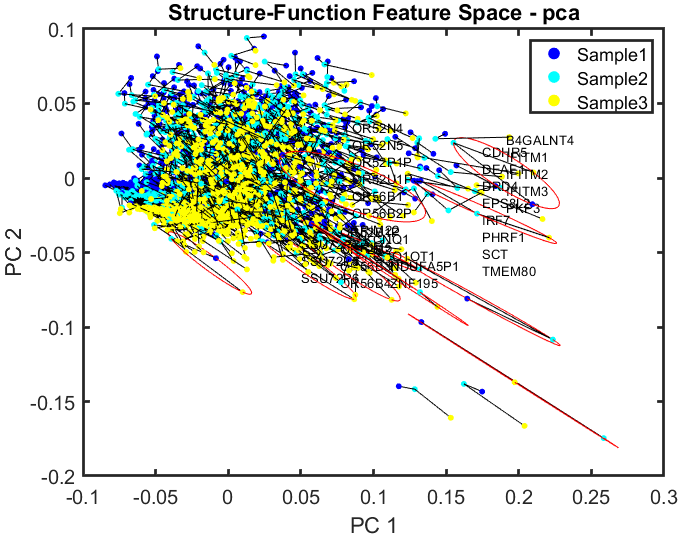

### Von Neumann Entropy

#### Simple Von Neumann Entropy - Two Cell Types

Von Neumann Entropy is calculated for Hi-C data (formatted as shown above) and can be used to compare the entropy of multiple cell types. In this example, we show two cell types, fibroblast and stem cell, to highlight the differences in chromatin organization.

The function **vneExample** requires the parameters **Data_Loc** and **Folder_Result** which denote the locations where the data can be accessed and the output figure is stored, respectively. The remaining parameters, **chrSelect**, **bpFrag**, and **binSize**, correspond to the chromosome used for analysis, the choice of coordinates (base pair = BP or fragment = FRAG), and the desired resolution of the data. The values assigned to these parameters shown below are the default if none are specified.

Data_Loc = {'data\exampleData\4DNFIFLJLIS5.hic',...
            'data\exampleData\4DNFIOX3BGNE.hic'}; %%% data input
Folder_Result = 'results\vneExampleResults'; %%% output folder
chrSelect = 14;
bpFrag = 'BP';
binSize = 1E5;

vneExample(Data_Loc, Folder_Result, chrSelect, bpFrag, binSize)

The VNE for an undifferentiatedcell type (embryonic stem cell, H1-hESC) is much higher than the more differentiated cell type (fibroblast,HFFc6).  Intra-chromosome log2(A) Hi-C matrices are shown at 100 kb resolution for chromosome 14.

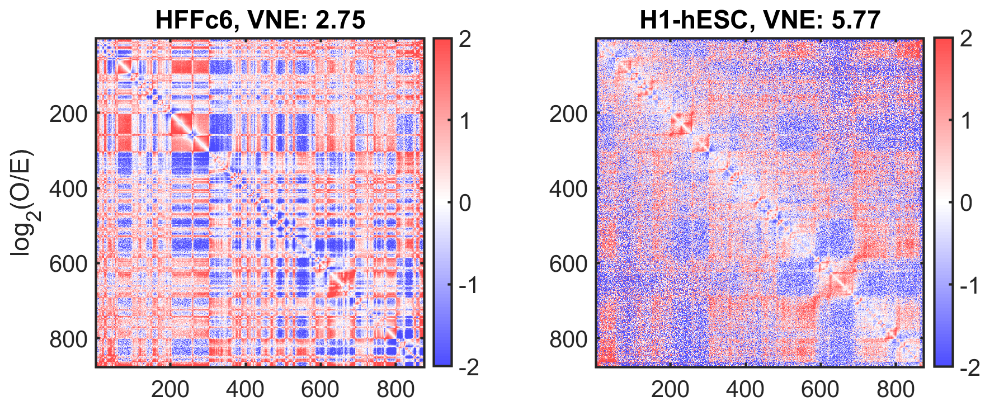

#### Expanded Von Neumann Entropy - Many Cell Types

The function **vneExampleExpanded **is similar to the simple VNE function above but highlights that more than two cell types can be calculated at once.

Data_Loc = {'data\exampleData\4DNFIFLJLIS5.hic';... %%% data input
            'data\exampleData\4DNFIOX3BGNE.hic';...
            'https://hicfiles.s3.amazonaws.com/hiseq/imr90/in-situ/combined.hic';...
            'https://hicfiles.s3.amazonaws.com/hiseq/huvec/in-situ/combined.hic';...
            'https://hicfiles.s3.amazonaws.com/hiseq/gm12878/in-situ/combined.hic';...
            'http://hicfiles.s3.amazonaws.com/hiseq/rpe1/DarrowHuntley-2015/WT-combined.hic'};
Folder_Result = 'results\vneExampleExpandedResults'; %%% output folder
chrSelect = 14;
bpFrag = 'BP';
binSize = 1E5;

vneExampleExpanded(Data_Loc, Folder_Result, chrSelect, bpFrag, binSize) 

Hi-C matrices are shown in order of VNE, left to right. The more pluripotent cell lines (hESC, HUVEC) have a much higher VNE than the more differentiated cell lines (IMR90, hHFF6c, GM12878). Intra-chromosome log2(A) Hi-C matrices are shown at 100 kb resolution forchromosome 14

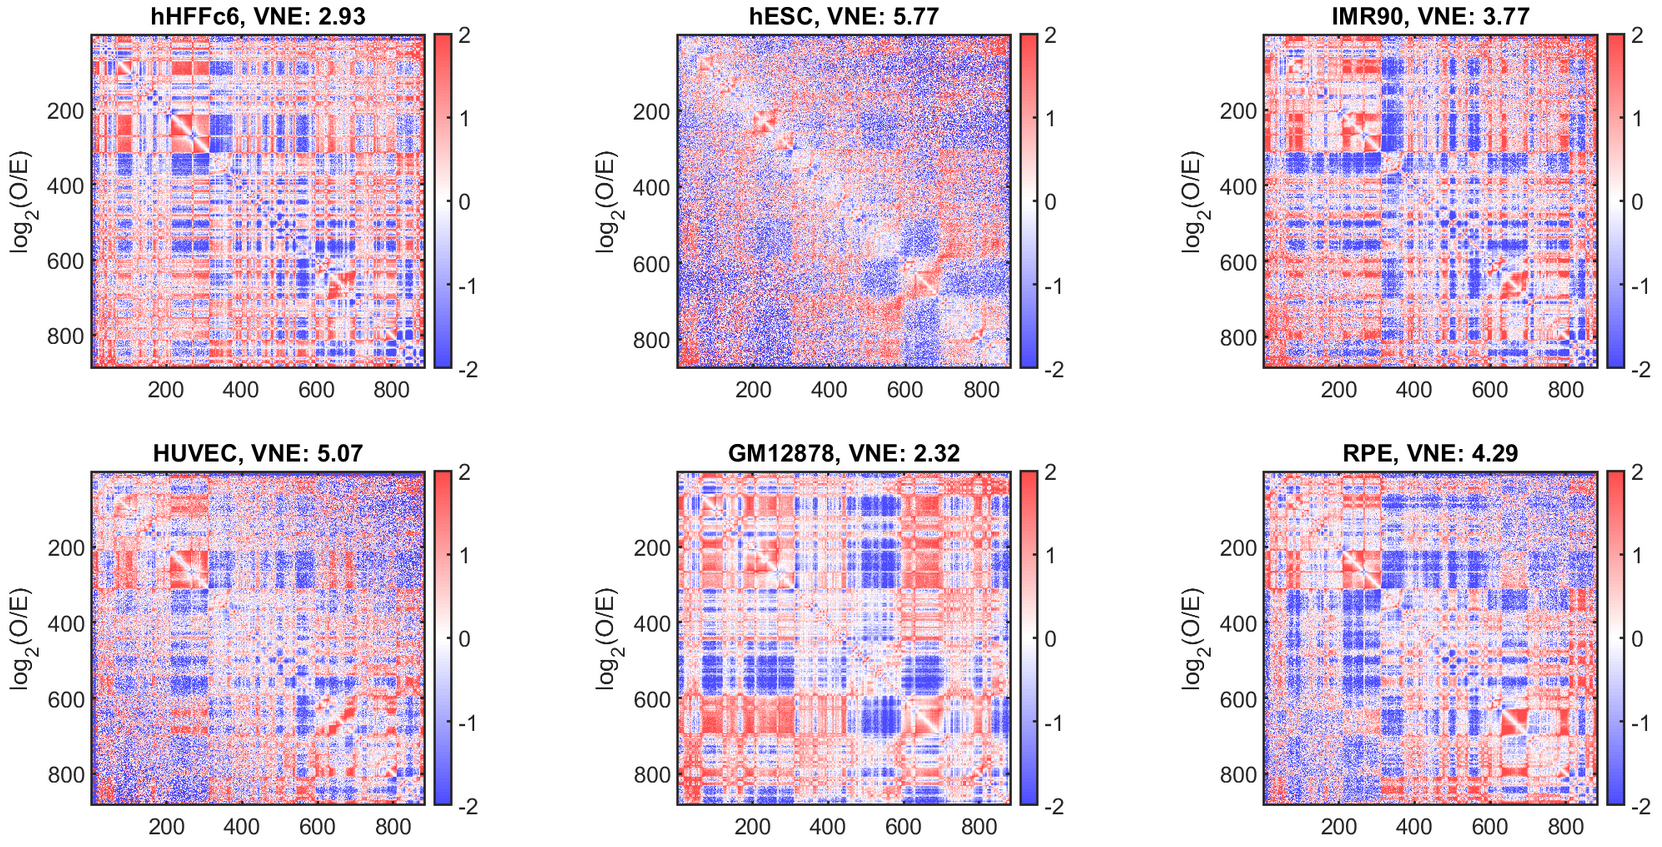

### Larntz-Perlman

The Larntz-Perlman method is used to compare Hi-C matrices from different cell types or time points. In this example, we show where a region of interest differs between three time points {-48, 8, 80 hours}. We recommend that the LP method is performed at Hi-C resolutions ≤100 kb and thatregions do not extend >5 Mb. The LP method also calculates a *P*-value for the equality of Hi-C matrices and the matrix S where the largest values in S correspond to genomic regions that are most different between samples.

The function **lpExample** requires the parameters **Data_Loc** and **Folder_Result** which denote the locations where the data can be accessed and the output figure is stored, respectively. Within the function **lpExample**, the specific region of interest can be modified by the user.

Data_Loc = 'data\exampleData\myodData\myodData.mat'; %%% data input
Folder_Result = 'results\lpExampleResults'; %%% output folder

lpExample(Data_Loc, Folder_Result);

The LP method highlights where samples are most significantly different within a region of interest.  

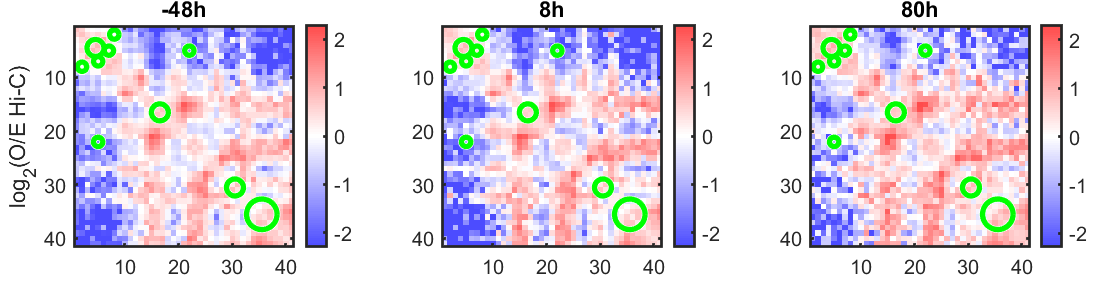

### Network Analysis

Data_Loc = 'data\exampleData\networkData\'; %%% data input folder
Folder_Result = 'results\networkExamplesResults'; %%% output folder

networkExamples(Data_Loc, Folder_Result);

Overlapping degree versus multiplex participation coefficient for multilayer networks corresponding to time periods {0, 8, 16, 24 hours} and {32, 40, 48, 56 hours}, respectively. The top 5% of genes yielding the largest position shift beforeand after bifurcation. 

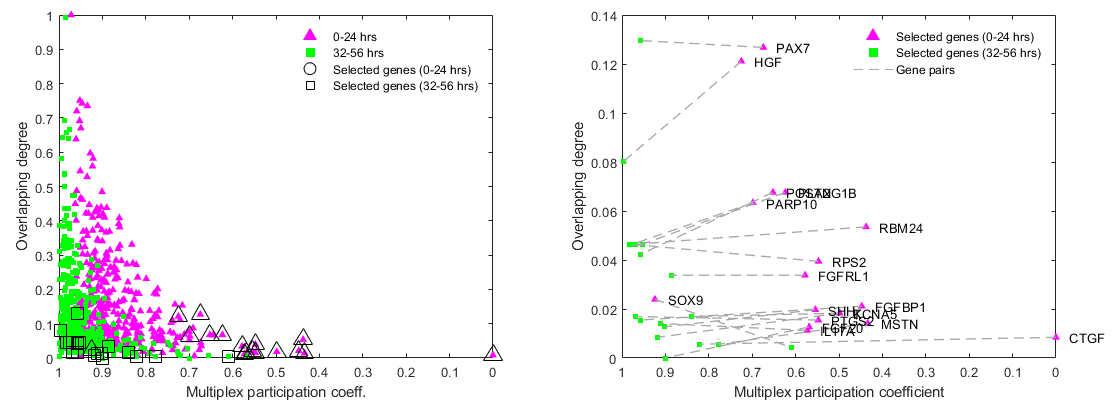

Network visualization of contact maps over 56 hours with highlighted genes RPM24, CTGF, and FGFBP1.

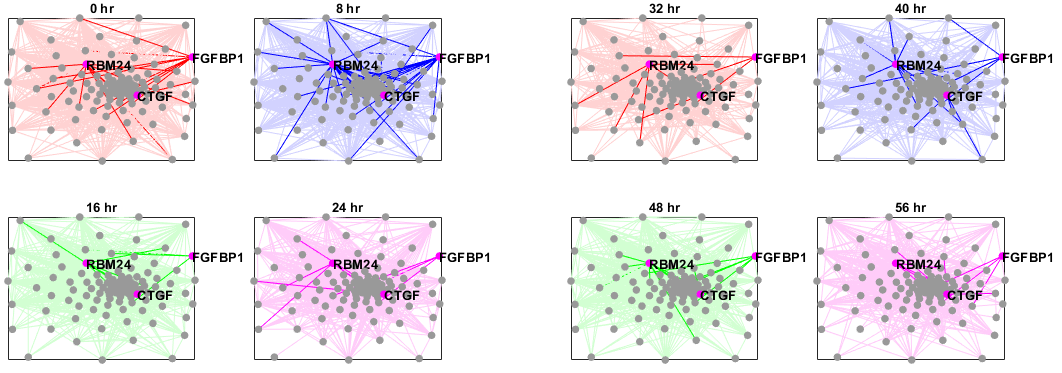

Summary of intra- and inter-chromosome contacts of extracted genes in cellular reprogramming versus fibroblast proliferation.